%Created by Jacobs Somnic on 20260314
%Latest revision: 
%Purpose: Vaccine simulation for n=2


clc;
clear all; 


%Parameter values
alpha=17;
beta=3; 
lambda=4;
mu=0.5;
delta1=1.5; 
theta1=2;
gamma1=2.5;
delta2=1;
theta2=2.5;

parameters=[alpha beta lambda mu delta1 theta1 gamma1 delta2 theta2];
parameters_EE=[alpha beta lambda mu delta1 theta1 gamma1 delta2 theta2];
parameters_DFE=[alpha 1 2 mu delta1 theta1 gamma1 delta2 theta2];
%Example of good set
%1. DFE is stable --> parameters=[1 1 1.4 0.5 0.5 0.6 0.7 0.7 0.8 0.376];

%Reproduction Number Calculation
R_0=(beta*lambda)/(mu*(mu+delta1+gamma1+theta1))

R_0 = 3.6923



%Constraint calculation
alpha_min=( delta1*gamma1*(delta2+2*mu)+(gamma1+theta1)*((delta2+2*mu)*(gamma1+2*mu)+2*mu*theta2) ) / (delta1*theta1)

alpha_min = 16.7500



%Initial Condition
S0=0.8;I10=0.2;I20=0;R0=0;
y0=[S0;I10;I20;R0];


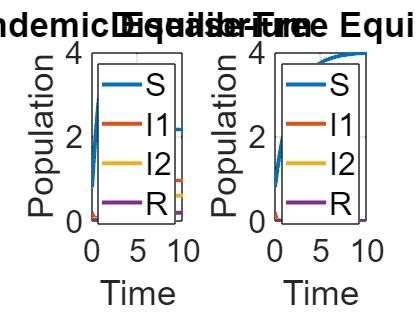

%Normal Plot
tspan=[0 10];


[t_EE,y_EE] = ode45(@(t,y) sirs(t,y,parameters_EE), tspan, y0);
[t_DFE,y_DFE] = ode45(@(t,y) sirs(t,y,parameters_DFE), tspan, y0);

figure('Name','EE vs DFE'); clf



subplot(1,2,1)
plot(t_EE,y_EE,'LineWidth',3)
title('Endemic Equilibrium','FontSize', 27)
xlabel('Time','FontSize', 24)
ylabel('Population','FontSize', 24)
legend('S','I1','I2','R','FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(1,2,2)
plot(t_DFE,y_DFE,'LineWidth',3)
title('Disease-Free Equilibrium','FontSize', 27)
xlabel('Time')
ylabel('Population')
legend('S','I1','I2','R','Location','east','FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

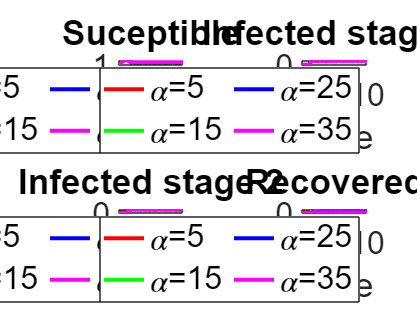


fig=gcf;

%Parameter Study
alpha_vector=[5 15 25 35];
col_vec=['r' 'g' 'b' 'm' 'c' 'k'];
figure('Name','Parameter Study'); clf
for i=1:length(alpha_vector)
    alpha=alpha_vector(i);
    parameters=[alpha beta lambda mu delta1 theta1 gamma1 delta2 theta2];

    [t,y] = ode45(@(t,y) sirs(t,y,parameters), tspan, y0);
    
    subplot(2,2,1)
    plot(t,y(:,1),col_vec(i),'LineWidth',3)
    hold on
    
    subplot(2,2,2)
    plot(t,y(:,2),col_vec(i),'LineWidth',3)
    hold on

    subplot(2,2,3)
    plot(t,y(:,3),col_vec(i),'LineWidth',3)
    title("Infected stage 2")
    hold on

    subplot(2,2,4)
    plot(t,y(:,4),col_vec(i),'LineWidth',3)
    hold on
end

subplot(2,2,1)
title("Suceptible",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
legend('\alpha=5','\alpha=15','\alpha=25','\alpha=35','Location','southeast','NumColumns',2,'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(2,2,2)
title("Infected stage 1",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
legend('\alpha=5','\alpha=15','\alpha=25','\alpha=35','Location','southeast','NumColumns',2,'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(2,2,3)
title("Infected stage 2",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
legend('\alpha=5','\alpha=15','\alpha=25','\alpha=35','Location','southeast','NumColumns',2,'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(2,2,4)
title("Recovered",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
legend('\alpha=5','\alpha=15','\alpha=25','\alpha=35','Location','east','NumColumns',2,'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;



hold off

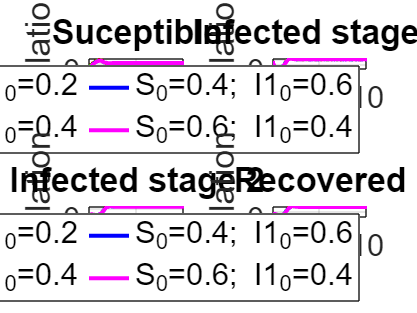



%Initial Condition Study
col_vec=['r' 'g' 'b' 'm' 'c' 'k'];
S0_vec=[0.8 0.6 0.4 0.2];
I01_vec=[0.2 0.4 0.6 0.8];

figure('Name','Initial Condition Study'); clf

parameters=[17 beta lambda mu delta1 theta1 gamma1 delta2 theta2];
for i=1:length(S0_vec)

    y0=[S0_vec(i);I01_vec(i);0;0];
    [t,y] = ode45(@(t,y) sirs(t,y,parameters), tspan, y0);

    subplot(2,2,1)
    plot(t,y(:,1),col_vec(i),'LineWidth',3)
    hold on
    
    subplot(2,2,2)
    plot(t,y(:,2),col_vec(i),'LineWidth',3)
    hold on

    subplot(2,2,3)
    plot(t,y(:,3),col_vec(i),'LineWidth',3)
    hold on

    subplot(2,2,4)
    plot(t,y(:,4),col_vec(i),'LineWidth',3)
    hold on

end

subplot(2,2,1)
title("Suceptible",'FontSize', 27)
xlabel("Time",'FontSize', 23)
ylabel("Population",'FontSize', 23)
legend('S_0=0.8; I1_0=0.2','S_0=0.6; I1_0=0.4','S_0=0.4; I1_0=0.6','S_0=0.6; I1_0=0.4','Location','southeast','NumColumns',2,'FontSize', 23)
grid on
ax=gca;
ax.FontSize=23;

subplot(2,2,2)
title("Infected stage 1",'FontSize', 27)
xlabel("Time",'FontSize', 23)
ylabel("Population",'FontSize', 23)
legend('S_0=0.8; I1_0=0.2','S_0=0.6; I1_0=0.4','S_0=0.4; I1_0=0.6','S_0=0.6; I1_0=0.4','Location','southeast','NumColumns',2,'FontSize', 23)
grid on
ax=gca;
ax.FontSize=23;

subplot(2,2,3)
title("Infected stage 2",'FontSize', 27)
xlabel("Time",'FontSize', 23)
ylabel("Population",'FontSize', 23)
legend('S_0=0.8; I1_0=0.2','S_0=0.6; I1_0=0.4','S_0=0.4; I1_0=0.6','S_0=0.6; I1_0=0.4','Location','southeast','NumColumns',2,'FontSize', 23)
grid on
ax=gca;
ax.FontSize=23;

subplot(2,2,4)
title("Recovered",'FontSize', 27)
xlabel("Time",'FontSize', 23)
ylabel("Population",'FontSize', 23)
legend('S_0=0.8; I1_0=0.2','S_0=0.6; I1_0=0.4','S_0=0.4; I1_0=0.6','S_0=0.6; I1_0=0.4','Location','east','NumColumns',2,'FontSize', 23)
grid on
ax=gca;
ax.FontSize=23;

function dydt = sirs(t,y,parameters)
    alpha=parameters(1);
    beta=parameters(2);
    lambda=parameters(3);
    mu=parameters(4);
    delta1=parameters(5); 
    theta1=parameters(6);
    gamma1=parameters(7);
    delta2=parameters(8);
    theta2=parameters(9);

    S=y(1);
    I1=y(2);
    I2=y(3);
    R=y(4);

    dS=lambda+alpha*R-mu*S-beta*S*I1;
    dI1=beta*S*I1-(mu+delta1+gamma1+theta1)*I1;
    dI2=gamma1*I1-(mu+delta2+theta2)*I2;
    dR=theta1*I1+theta2*I2-(alpha+mu)*R;

    dydt = [dS; dI1; dI2; dR];
end